## **Matlab Assignement            **

**                     Ebad Syed**

**23.** An LTI system is described by the difference equation

**y[n] = bx[n] + 0.8y[n − 1] − 0.81y[n − 2].**

% Defining the LTI System

a = [1,-0.8,0.81];
b = [1];

(d) Determine analytically the response y[n] to the **input x[n] = 2 cos(πn/3 + 45**).

**(e) Using MATLAB compute the steady-state response to x[n] above.**

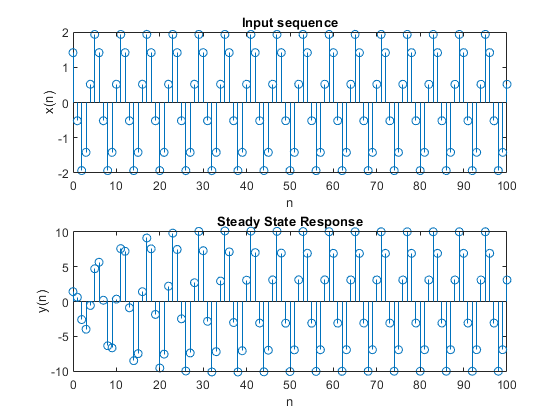

n=[0:100];

% Defining x[n]
x = 2 * cos((1/3)*pi*n + 45*(pi/180));
% Calculating the Steady State Response
y = filter(b,a,x);

figure();
% Plotting the Input and Steady State Response
subplot(2,1,1); stem(n,x);
xlabel('n'); ylabel('x(n)'); title('Input sequence')
subplot(2,1,2); stem(n,y);
xlabel('n'); ylabel('y(n)'); title('Steady State Response')

**31.** A multiband ideal bandpass filter is given by

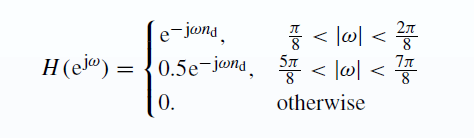

**(c) From the above truncated impulse response, compute and plot the magnitude**

**response of the filter using MATLAB and compare it with the ideal filter response.**

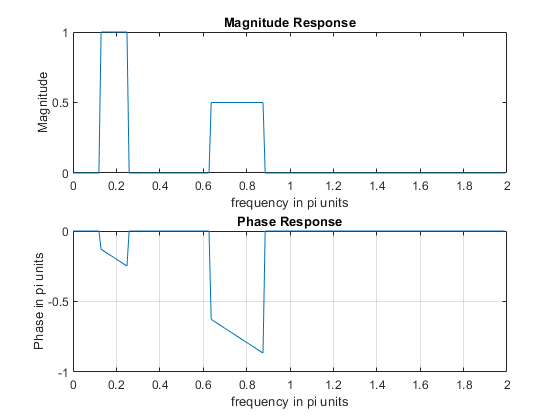

b1 = [0,1]; a1 = [1];
b2 = [0,0.5]; a2 = [1];

n=-100:1:100;

% Frequency Response

[h1,w1] = freqz(b1,a1,201,'whole');
[h2,w2] = freqz(b2,a2,201,'whole');

% Turncation based on limits

h00 = zeros(13,1);
h11 = h1(14:26);
h110 = zeros(38,1);
h22 = h2(64:88);
h220 = zeros(200-88,1);

% Final Response
h = cat(1,h00,h11,h110,h22,h220);

% Magnitude and Phase Plot
magH = abs(h); phaH = angle(h);
figure()
subplot(2,1,1);plot(w1/pi,magH);
xlabel('frequency in pi units'); ylabel('Magnitude');
title('Magnitude Response')
subplot(2,1,2);plot(w1/pi,phaH/pi);grid
xlabel('frequency in pi units'); ylabel('Phase in pi units');
title('Phase Response')

**46.** An LTI system is described by the difference equation** y[n] = x[n] − x[n − 4] −0.81y[n − 2] − 0.6561y[n − 4].**

a = [1,0,0.81,0,0.6561];
b = [1,0,0,0,-1];

(d) Determine analytically the response y[n] to the input **x[n] = 2 cos(0.5πn+60)+sin(πn/3 − 45)**.

(e) Using MATLAB compute the steady-state response to x[n] above and verify your

result.

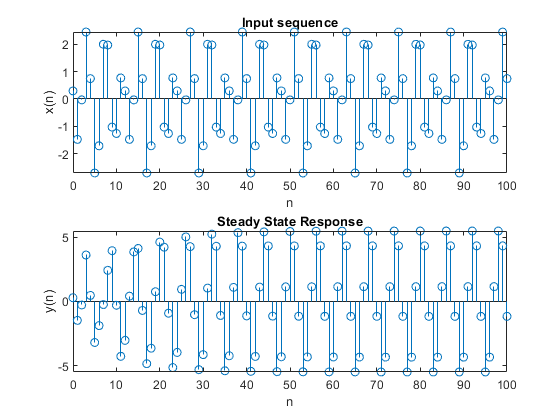

n=[0:100];

% Defining x[n]
x = 2 * cos((1/2)*pi*n + 60*(pi/180)) + sin(pi*n/3 - 45*pi/180);
% Calculating the Steady State Response
y = filter(b,a,x);

figure();
% Plotting the Input and Steady State Response
subplot(2,1,1); stem(n,x);
xlabel('n'); ylabel('x(n)'); title('Input sequence')
subplot(2,1,2); stem(n,y);
xlabel('n'); ylabel('y(n)'); title('Steady State Response')

54

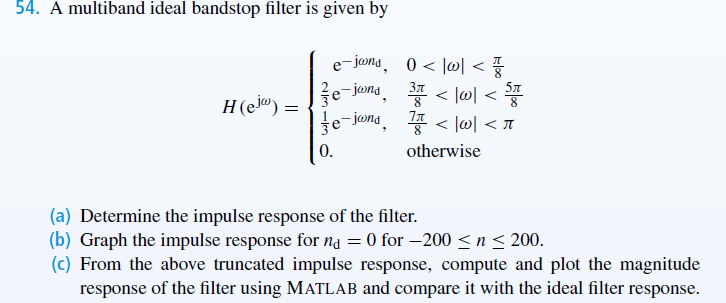

clear;
w1=linspace(0,pi/8,401);
w2=linspace(3*pi/8,5*pi/8,401);
w3=linspace(7*pi/8,pi,401);
k=0;
% Using synthesis equation we find the impulse response
for n=-200:1:200
    k=k+1;
    h1(k)=(1/(2*pi))*trapz(w1,exp(1i*w1*n));
    h2(k)=(1/(2*pi))*(2/3)*trapz(w2,exp(1i*w2*n));
    h3(k)=(1/(2*pi))*(1/3)*trapz(w3,exp(1i*w3*n));
end

% Complete Impulse Response is given by
h=h1+h2+h3;
n=-200:1:200;
figure()
subplot(311)
stem(n,h)

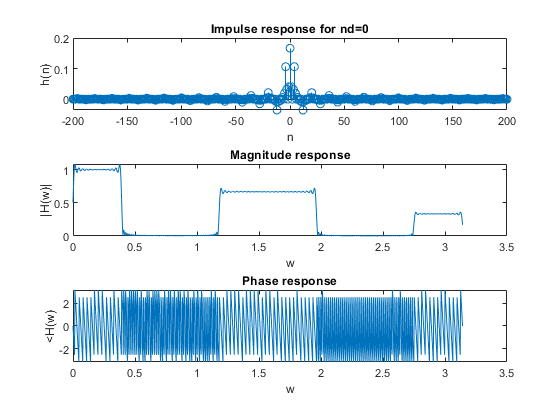

title('Impulse response for nd=0')
xlabel('n')
ylabel('h(n)')

%to find magnitude and phase of truncated impulse response h(n)
w=0:(pi/1000):pi;
[H,w]=freqz(h,1,w);
subplot(312)
plot(w,abs(H))
title('Magnitude response')
xlabel('w')
ylabel('|H(w)|')
subplot(313)
plot(w,angle(H))
title('Phase response')
xlabel('w')
ylabel('<H(w)')